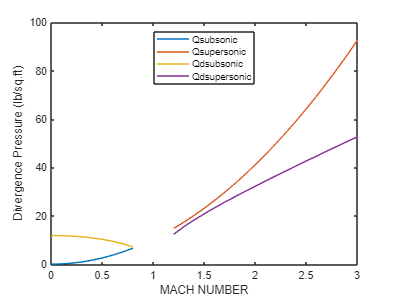

clc;
clear;
k=7000;
b=100;
e=25;
s=22000;
specificheat=1.4;
P_sealevel=14.7;

m1=(0:0.1:0.8);
m2=(1.2:.1:3);

Cla_subsonic=((2.*pi)./sqrt(1-m1.^2));
Cla_supersonic=((4)./sqrt(m2.^2-1));
Qd_subsonic=0.5858*((k*b.^2)./(s*e*Cla_subsonic));
Qd_supersonic=0.5858*((k*b.^2)./(s*e*Cla_supersonic));

Q_sealevel_sub=(specificheat/2)*(P_sealevel*m1.^2);
Q_sealevel_sup=(specificheat/2)*(P_sealevel*m2.^2);

plot(m1,Q_sealevel_sub,m2,Q_sealevel_sup,m1,Qd_subsonic,m2,Qd_supersonic);
legend('Qsubsonic','Qsupersonic','Qdsubsonic','Qdsupersonic','Location','north');
xlabel('MACH NUMBER');
ylabel('Divergence Pressure (lb/sq.ft)');